# PSO Toolbox

*Autor: Eduardo Andrés Santizo Olivet (16089)*

### Setup Matlab

% Chequea si no existen errores de sintaxis en el archivo
% "functionSignatures.json" utilizado para generar sugerencias
% personalizadas para las funciones del Toolbox.
validateFunctionSignaturesJSON;    

validateFunctionSignaturesJSON completed without producing any messages.



% Limpieza de Workspace
clear;                                                      % Se limpian las variables del workspace
clear ComputeInertia;                                       % Se limpian las variables persistentes presentes dentro de "ComputeInertia.m"
clear CostFunction;
 

### Parámetros PSO

NoParticulas = 10;                                          % No. de partículas
PartPosDims = 2;                                            % No. de variables a optimizar / No. de dimensiones sobre las que se pueden desplazar las partículas.

CostFunc = "APF";                            % Función de costo a optimizar. Escribir "help CostFunction" para más información
Multiples_Min = 0;                                          % La función de costo tiene múltiples mínimos? Consultar "help CostFunction" para ver número de mínimos por función.

DimsMesa = 12;                                              % Dimensiones de mesa de simulación (Metros)
PosMax = DimsMesa / 2;                                      % Posición máx: Valor máx. para las coordenadas X y Y de las partículas (Asumiendo un plano de búsqueda cuadrado)
PosMin = -PosMax;                                           % Posición mín: Negativo de la posición máxima
Margen = 0.4;                                               % Ancho de margen alrededor de los bordes

InitTime = 0;                                               % Tiempo de inicio del algoritmo (0s)
EndTime = 10;                                               % Duración de algoritmo en segundos 
dt = 0.07;                                                  % Tiempo de muestreo, diferencial de tiempo o "time step"
IteracionesMax = ceil((EndTime - InitTime) / dt);           % Iteraciones máximas que podrá llegar a durar la simulación.

EnablePucks = 0;
RadioLlantasPuck = 0.2;                                     % Radio de las ruedas del E-Puck
RadioCuerpoPuck = 0.35;                                     % Radio del Cuerpo del E-Puck en metros
RadioDisomorfismo = RadioCuerpoPuck;                        % Distancia entre centro y punto de disomorfismo
PuckVelMax = 6;

ModoVisualizacion = "3D";                                   % Modo de visualización: 2D, 3D o None.
%rng(20185);                                                % Se fija la seed a utilizar para la generación aleatoria de números. Hace que los resultados sean replicables.

### Inicialización de Criterios de Convergencia

Criterios_Activados = [];                                   % El vector de criterios activados es nulo
Criterios = zeros(1,4);                                     % Se inicializan todos los criterios como "No alcanzados" (Iguales a cero)

### Obstáculos en Escenario

% Punto al que deben llegar las partículas (Únicamente válido para una
% función de costo basada en "Artificial Potential Fields" o APF.
Meta = [-3 -3];

% Tipo de obstáculo a colocar en el espacio de tarea. Opciones:
%   - Poligono: El usuario puede dibujar el obstáculo
%   - Cilindro: Círculo o cilindro en el centro de la mesa
%   - Caso A: Caso A del trabajo de investigación de Cahueque J.
%   - Caso B: Caso B del trabajo de investigación de Cahueque J.
%   - Caso C: Caso C del trabajo de investigación de Cahueque J.
TipoObstaculo = "Cilindro";
RadioObstaculo = 1;                                                     % Únicamente válido para el obstáculo tipo "Cilindro"
AlturaObstaculo = 1;
OffsetObstaculo = 0;

switch TipoObstaculo
    
    case "Poligono"
        [XObs,YObs,ZObs] = DrawObstacles(TipoObstaculo, AlturaObstaculo, OffsetObstaculo, PosMin, PosMax);
        
    case "Cilindro"
        [XObs,YObs,ZObs] = DrawObstacles(TipoObstaculo, AlturaObstaculo, OffsetObstaculo, RadioObstaculo);

    case "Caso A"
        XObs = [-2 -2 0 0 -2]'; YObs = [-7 7 7 -7 -7]';
        XObs = interp1([-10 10],[PosMin PosMax],XObs);
        YObs = interp1([-10 10],[PosMin PosMax],YObs);
        [XObs,YObs,ZObs] = DrawObstacles("Custom",AlturaObstaculo,OffsetObstaculo,XObs, YObs);
    
    case "Caso B"
        XObs = [0 0 2 2 0]'; YObs = [-2 2 2 -2 -2]';
        XObs = interp1([-10 10],[PosMin PosMax],XObs);
        YObs = interp1([-10 10],[PosMin PosMax],YObs);
        [XObs,YObs,ZObs] = DrawObstacles("Custom",AlturaObstaculo,OffsetObstaculo,XObs, YObs);
        
    case "Caso C"
        Meta = [-3 0];
        XObs = [-6 -6 -5 -5 -6 NaN -6 -6 -5 -5 -6 NaN -1 -1 0  0 -1]';
        YObs = [-5 -4 -4 -5 -5 NaN  5  4  4  5  5 NaN -1  0 0 -1 -1]';
        XObs = interp1([-10 10],[PosMin PosMax],XObs);
        YObs = interp1([-10 10],[PosMin PosMax],YObs);
        [XObs,YObs,ZObs] = DrawObstacles("Custom",AlturaObstaculo,OffsetObstaculo,XObs, YObs);
end

### Parámetros Ambientales (Environment Parameters)

Según el tipo de función de costo a utilizar, la función puede llegar a requerir de más o menos parámetros. Funciones Benchmark no requieren parámetros adicionales, pero por ejemplo la función de APF requiere de parámetros como los vértices de los obstáculos (XObs / YObs), las posiciones máxima y mínima de la mesa de trabajo o robotat (PosMin / PosMax) y el punto de meta (Meta). Jabandzic requiere de aún más parámetros. Entonces para darle mayor flexibilidad al usuario, este puede definir en el switch case presente más adelante, la cantidad de parámetros adicionales que le desea pasar a la función de costo programada. Este solo debe tomar en cuenta los inputs adicionales en el input parser de la función `CostFunction.m`

% Posición y Velocidad de Partículas
PartPosicion_Actual = unifrnd(2, 5, [NoParticulas PartPosDims]);                % Posición (Random) de todas las partículas. Distribución uniforme.     Dims: NoParticulas X VarDims

% Se chequean las posiciones y se verifica si están dentro de un obstáculo.
% Si lo están, se corrigen para que no se inicien sobre un obstáculo.
InObs = 1;
while sum(InObs) ~= 0
    InObs = inpolygon(PartPosicion_Actual(:,1),PartPosicion_Actual(:,2),XObs(:,1),YObs(:,1));
    PartPosicion_Correccion = unifrnd(PosMin, PosMax, [NoParticulas PartPosDims]);
    PartPosicion_Actual = PartPosicion_Actual + PartPosicion_Correccion .* InObs;
end

% Parámetros adicionales para funciones de costo no estándar
switch CostFunc
    case "APF"
        EnvironmentParams = {XObs(:,1), YObs(:,1), PosMin, PosMax, Meta};
        
    case "Jabandzic"
        EnvironmentParams = {XObs(:,1), YObs(:,1), PosMin, PosMax, Meta, PartPosicion_Actual};
        
    otherwise
        EnvironmentParams = {};
end

### Búsqueda Numérica del Mínimo de la "Cost Function"

Siempre debe realizarse este paso previo a inicializar los algoritmos de optimización ya que en el caso de algunos métodos (APF por ejemplo) la función de costo debe ser inicializada previo a poder ser utilizada. 

% Imaginar que se tiene un plano coordenado que va tanto en X y Y desde PosMin a PosMax 
% con un step de 0.01. MeshX consiste de todas las coordenadas X de ese plano y MeshY 
% consiste de todas las coordenadas Y de ese plano. 
Resolucion = 0.1;
[MeshX, MeshY] = meshgrid(PosMin-Margen:Resolucion:PosMax+Margen, PosMin-Margen:Resolucion:PosMax+Margen);

% Se redimensionan MeshX y MeshY como vectores columna y luego se concatenan. El resultado 
% es una matriz de dos columnas (Coordenadas X y Y) donde las filas consisten de todas las 
% posibles combinaciones de coordenadas que pueden existir en el plano de búsqueda. 
Mesh2D = [MeshX(:) MeshY(:)];

% Cálculo de superficie o función de costo
CostoPart = CostFunction(Mesh2D, CostFunc, EnvironmentParams{:});

% NOTA: El programa debería ser capaz de identificar numéricamente los mínimos de la función 
% evaluando los puntos del mesh en la cost function. En caso no se detecten bien. Disminuir 
% el valor de resolución o revisar si la opción de "Multiples_Min" está habilitada (En caso
% se esté utilizando una función de múltiples mínimos.
Altura = reshape(CostoPart, size(MeshX, 1), size(MeshX, 2));                            % Evaluación de todas las coords. del plano en la "Cost Function". El "output vector" (Nx1) se redimensiona a la forma de MeshX  
MaxAltura = max(max(Altura));                                                           % Se obtiene el costo máximo de todo el plano.
MinAltura = min(min(Altura));                                                           % Se obtiene el costo mínimo de todo el plano.
SpanAltura = MaxAltura - MinAltura;                                                     % Diferencia entre ambas alturas

if Multiples_Min                                                                        % Utilizar un threshold de detección más bajo para funciones con múltiples mínimos globales.
    Threshold_Cercania = 10^-2;                                                         % Modificar en caso no se detecten bien todos los mínimos globales de una función con múltiples mínimos absolutos.
else             
    Threshold_Cercania = 10^-5;     
end

%PlotSupCosto = contour(MeshX, MeshY, Altura, 'HandleVisibility','off'); 
IndexMin = find(abs(Altura(:) - MinAltura) < Threshold_Cercania);                       % Distancia del mínimo del plano al resto de puntos. Se retornan las coordenadas de los puntos a una distancia < "Threshold_Cercania"
Coords_Min = Mesh2D(IndexMin,:);                                                        % Coordenadas (Fila de Mesh2D) donde se encuentra el/los costo(s) mínimo(s) global(es)

% Se limpian los mínimos encontrados en caso se hayan detectado réplicas de
% la misma coordenada. Útil debido a la forma numérica y algo "brute forced"
% de la solución utilizada para encontrar mínimos.
i = 1;
while i < size(Coords_Min,1)
    DistMins = sqrt(sum((Coords_Min - Coords_Min(i,:)).^2, 2));                         % Se calcula la distancia euclideada del mínimo "i" al resto.
    Coords_Min((DistMins < 0.1) & (DistMins ~= 0),:) = [];                              % Se eliminan las filas de "Coords_Min" cuya distancia euclideada sea menor a 0.1 y distinta de 0.
    i = i+1;
end

% Si la función de costo utilizada no requiere de la especificación manual
% de una meta, entonces la variable "Meta" toma el valor de las coordenadas
% con la menor altura o "Coord_Min".
switch CostFunc
    case {"APF", "Jabandzic"}
        % Meta permanece inalterada.
        
    otherwise
        Meta = Coords_Min;
end

### Inicialización de Posiciones, Velocidades y Costos

% Inicialización de algoritmo de optimización PSO.
CostFunction(PartPosicion_Actual, CostFunc, EnvironmentParams{:});
Part = PSO(PartPosicion_Actual, CostFunc, IteracionesMax, EnvironmentParams);

% Posición y Velocidad de Pucks
PuckPosicion_Actual = Part.Posicion_Actual;                                     % Posición de los Pucks. Inicialmente igual a la de las partículas.     Dims: NoParticulas X VarDims
PuckPosicion_Previa = Part.Posicion_Previa;                                     % Memoria con la posición previa de todos los pucks.                    Dims: NoParticulas X VarDims
PuckVelLineal = zeros(NoParticulas, 1);                                         % Velocidad lineal de todos los pucks. Inicialmente 0.                  Dims: NoParticulas X VarDims
PuckVelAngular = PuckVelLineal;

% Historial de las Velocidades Lineal y Angular de los Pucks
PuckVelLineal_History = zeros(NoParticulas, IteracionesMax);
PuckVelAngular_History = zeros(NoParticulas, IteracionesMax);
PuckVelLineal_History(:,1) = PuckVelLineal;
PuckVelAngular_History(:,1) = PuckVelAngular;

% Historial de Posiciones de Pucks
PuckPosicionX_History = zeros(NoParticulas, IteracionesMax);
PuckPosicionY_History = zeros(NoParticulas, IteracionesMax);
PuckPosicionX_History(:,1) = PuckPosicion_Actual(:,1);
PuckPosicionY_History(:,1) = PuckPosicion_Actual(:,2);

% Orientación de Pucks
% La indicación de la orientación es una línea que apunta hacia el frente
% del Puck. Los componentes (X,Y) de esta linea indicadora se almacenan en 
% la matriz "CompLineaOrientacion"
PuckOrientacion_Actual = unifrnd(0, 2*pi, [NoParticulas 1]);                    % Orientaciones aleatorias para los pucks. Valores entre 0 y 2pi        Dims: NoParticulas X 1 (Vector Columna)
CompLineaOrientacion = RadioCuerpoPuck * ...                                    %                                                                       Dims: NoParticulas X 2 (Columna por componente: X, Y)
                       [cos(PuckOrientacion_Actual) sin(PuckOrientacion_Actual)];                                             

% Costo de E-Pucks
PuckCosto_Local = Part.Costo_Local;                                              % Inicialmente todos los costos son iguales a los de las partículas
PuckCosto_LocalBest = Part.Costo_LocalBest;
PuckCosto_GlobalBest = Part.Costo_GlobalBest;

% Historia de todos los global best
Costo_History = zeros([IteracionesMax 2]);                                      % Historial de todos los "Costo_Global" o global best de cada iteración
Costo_History(1,:) = [Part.Costo_GlobalBest PuckCosto_GlobalBest];              % La primera fila del vector es el primer "Global Best" de las partículas y los pucks

### Coeficientes de Constricción / Coeficiente de Inercia

De acuerdo con Poli, Kennedy y Blackwell (2007) en su artículo: "Particle Swarm Optimization - Swarm Intelligence", el algoritmo de PSO original tenía la siguiente forma


$$v\left(t+1\right)=v\left(t\right)+\overrightarrow{U} \left(0,\phi_1 \right)\otimes \left(\overrightarrow{p_{\textrm{local}} } -\overrightarrow{x_i } \right)+\overrightarrow{U} \left(0,\phi_2 \right)\otimes \left(\overrightarrow{p_{\textrm{global}} } -\overrightarrow{x_i } \right)$$



$$x\left(t+1\right)=x\left(t\right)+v\left(t+1\right)$$


Donde:

- $\overrightarrow{U} \left(0,\phi_1 \right)$: Consiste de un número uniformemente distribuido entre 0 y $\phi_1 \;$

- $\otimes$: Consiste del "element-wise product".

Este presentaba ciertos problemas de inestabilidad, en particular porque el término de la velocidad actual ($v\left(t\right)$) tendía a crecer desmesuradamente. Para limitarlo, la primera solución propuesta por Kennedy y Eberhart (1995) fue truncar los posibles valores que podía llegar a tener la velocidad de una partícula a un valor entre (-Vmax, Vmax). Esto producía mejores resultados, pero la selección de Vmax requería de una gran cantidad de pruebas para poder obtener un valor óptimo para la aplicación dada. Poco después Shi y Eberhart (1998) propusieron una modificación a la regla de actualización de la velocidad de las partículas: La adición de un coeficiente $\omega$ multiplicando a la velocidad actual.


$$v\left(t+1\right)=\omega \;v\left(t\right)+\overrightarrow{U} \left(0,\phi_1 \right)\otimes \left(\overrightarrow{p_{\textrm{local}} } -\overrightarrow{x_i } \right)+\overrightarrow{U} \left(0,\phi_2 \right)\otimes \left(\overrightarrow{p_{\textrm{global}} } -\overrightarrow{x_i } \right)$$


A este término se le denominó coeficiente de inercia, ya que si se hace un análogo entre la regla de actualización y un sistema de fuerzas, el coeficiente representa la aparente "fluidez" del medio en el que las partículas se mueven. La idea de esta modificación era iniciar el algoritmo con una fluidez alta ($\omega =0\ldotp 9$) para favorecer la exploración y reducir su valor hasta alcanzar una fluidez baja  ($\omega =0\ldotp 4$) que favorezca la agrupación y convergencia. Existen múltiples métodos para seleccionar y actualizar $\omega$. Finalmente, el método más reciente para limitar la velocidad consiste de aquel propuesto por Clerc y Kennedy (2001). En este, se modeló al algoritmo como un sistema dinámico y se obtuvieron sus eigenvalores. Se pudo llegar a concluir que, mientras dichos eigenvalores cumplieran con ciertas relaciones, el sistema de partículas siempre convergería. Una de las relaciones más fáciles y computacionalmente eficientes de implementar consiste de la siguiente modificación al PSO:


$$v\left(t+1\right)=\chi \;\left(\;v\left(t\right)+\overrightarrow{U} \left(0,\phi_1 \right)\otimes \left(\overrightarrow{p_{\textrm{local}} } -\overrightarrow{x_i } \right)+\overrightarrow{U} \left(0,\phi_2 \right)\otimes \left(\overrightarrow{p_{\textrm{global}} } -\overrightarrow{x_i } \right)\right)$$



$$\chi =\frac{2}{\phi -2+\sqrt{\;\phi {\;}^2 -4\phi \;}}$$



$$\phi =\phi_1 +\phi_2 >4$$


Al implementar esta constricción (Generalmente utilizando $\phi_1 =\phi_2 =2\ldotp 05$), se asegura la convergencia en el sistema, por lo que teóricamente ya no es necesario truncar la velocidad. Un aspecto importante a mencionar es que comúnmente se tiende a distribuir la constante $\chi$ en toda la expresión de la siguiente manera:


$$v\left(t+1\right)=\chi \;\;v\left(t\right)+\chi \overrightarrow{U} \left(0,\phi_1 \right)\otimes \left(\overrightarrow{p_{\textrm{local}} } -\overrightarrow{x_i } \right)+\chi \overrightarrow{U} \left(0,\phi_2 \right)\otimes \left(\overrightarrow{p_{\textrm{global}} } -\overrightarrow{x_i } \right)$$



$$\left.v\left(t+1\right)=\chi \;\;v\left(t\right)+C_1 \otimes \left(\overrightarrow{p_{\textrm{local}} } -\overrightarrow{x_i } \right)+C_2 \otimes \left(\overrightarrow{p_{\textrm{global}} } -\overrightarrow{x_i } \right)\right)$$


Aquí se puede llegar a ver más claramente como $\chi$ consiste del nuevo valor para el coeficiente de inercia, por lo que la adición de una constante $\omega$ sería redundante o incluso detrimental para el algoritmo (Ya que introduce efectos imprevistos en la estabilidad del sistema). De cualquier manera se puede experimentar incluyendo ambas constantes y observando los efectos que su adición simultánea tiene en el sistema.

% -------------------------------------------------------------------------
% A continuación se presentan tres opciones para restringir la velocidad: 
%   - Utilizar el coeficiente de constricción (Chi) limitando Vmax a Xmax
%   - Utilizar un coeficiente de inercia limitando Vmax a un valor elegido 
%     por el usuario
%   - Mezclar ambos métodos. Método utilizado por Aldo Nadalini en su tésis.
% -------------------------------------------------------------------------
                  
Part.SetRestricciones("Constriccion",PosMin,PosMax);                            % Modo de restricción: Constriccion / Inercia / Mixto


### Colores / Paleta

Naranja = [0.9290 0.6940 0.1250];

### Settings de Gráficación / Setup Gráficos

SaveFrames = 0;                                                                 % Guardar frames de animación: 1 = Si / 0 = No.
SaveVideo = 0;
FrameSkip = 3;                                                                  % Cada cuantas frames se toma un screenshot. Valor recomendado = 3

if ~strcmp(ModoVisualizacion, "None")
    
    if SaveVideo
        NombreVideo = "Output" + ModoVisualizacion + ".mp4";
        Video = VideoWriter(NombreVideo,'MPEG-4');
        Video.FrameRate = 30;
        open(Video);
    end
    
    close all;
    figure('Name',"Simulación PSO"); clf;                                       % Se limpia la figura 1
    figure('visible','on');                                                     % Opcional. Utilizado para mostrar animaciones en un ".mlx". Si se utiliza un ".m" se puede comentar.
    axis equal;                                                                 % Ejes con escalas iguales y cuadrícula habilitada.
    
    FigureWidth = 700;                                                          % Ancho del plot en "pts"
    FigureHeight = 500;                                                         % Alto del plot en "pts"
    ScreenSize = get(0,'ScreenSize');                                           % Se obtiene el tamaño de la pantalla. ScreenSize(3) = Ancho / ScreenSize(4) = Alto
    
    % Centra la figura en pantalla
    set(gcf, 'Position',  [ScreenSize(3)/2 - FigureWidth/2, ScreenSize(4)/2 - FigureHeight/2, FigureWidth, FigureHeight])
    
    % El radio del puck está en metros, pero debe ser reexpresado en puntos
    % para ser utilizado en "scatter()" y "scatter3()"
    ax = gca;                                                                   % Propiedades de "axis" o ejes actuales
    old_units = get(ax, 'Units');                                               % Unidades de los ejes actuales
    set(ax, 'Units', 'points');                                                 % Se cambian las unidades de los ejes a puntos
    PosAxis = get(ax, 'Position');                                              % Se obtiene el [left bottom width height] de la caja que encierra a los ejes
    set(ax, 'Units', old_units);                                                % Se regresa a las unidades originales de los ejes
    DimsMesaPuntos = min(PosAxis(3:4));                                         % Se obtiene el valor mínimo entre el "width" y el "height" de los axes en "points"
    FactorConversion = DimsMesaPuntos / DimsMesa;
    AreaPuckScatter = pi*(RadioCuerpoPuck * FactorConversion)^2;
    
    % Subplot 2 (Fila 1, Columna 2): Graficación de partículas
    switch ModoVisualizacion
        case "2D"
            axis([PosMin PosMax PosMin PosMax]);                                                                                        % Limites Plot: Tanto X como Y van de PosMin a PosMax 
            PlotSupCosto = contour(MeshX, MeshY, Altura, 'HandleVisibility','off');                                                     % Contour Plot: Curvas de nivel de función o superficie de costo
            hold on; axis manual; alpha 0.5; grid on; grid minor;                                                                       %   Graficar en el mismo plot / Transparencia del 50%
            
            PlotParticulas = scatter(PartPosicion_Actual(:,1), PartPosicion_Actual(:,2),[],'black');                                    % Scatter Plot: Partículas. Puntos negros.
            
            DetallesPlot = {"No. Pucks: " + num2str(NoParticulas) ; ...
                            "Cost Function: " + CostFunc ; ...                                                                         
                            "Meta: (" + num2str(Meta(1)) + "," + num2str(Meta(2)) + ")"};
            annotation('textbox', [0.725, 0.6, 0.22, 0], 'string', DetallesPlot,'FontSize', 8);                                          % Anotación: Detalles propios de la simulación
            
            if strcmp(CostFunc,"APF") || strcmp(CostFunc,"Jabandzic")
                PlotPuntoMin = scatter(Meta(1), Meta(2), 'red', 'x');                                                                   % Scatter Plot: Meta de APF / Jabandzic
                Obstaculo = fill(XObs(:,1),YObs(:,1),'b','FaceAlpha',0.2);
                
                MarcoInteriorX = [PosMin PosMax PosMax PosMin PosMin];
                MarcoInteriorY = [PosMin PosMin PosMax PosMax PosMin];
                MarcoExteriorX = [PosMin-Margen PosMax+Margen PosMax+Margen PosMin-Margen PosMin-Margen];
                MarcoExteriorY = [PosMin-Margen PosMin-Margen PosMax+Margen PosMax+Margen PosMin-Margen];
                MarcoExterior = fill([MarcoInteriorX MarcoExteriorX],[MarcoInteriorY MarcoExteriorY],'b','FaceAlpha',0.2);              % Fill: Marco que representa los bordes del Robotarium
                
            else
                PlotPuntoMin = scatter(Meta(:,1), Meta(:,2), 'red', 'x');                                                               % Scatter Plot: Mín función de costo = Cruz roja
            end
            
            if EnablePucks
                PlotPucks = scatter(PuckPosicion_Actual(:,1), PuckPosicion_Actual(:,2), AreaPuckScatter, 'blue', 'LineWidth', 1.5);     % Scatter Plot: Pucks. Circulos azules.
                PlotLineasOrientacion = quiver(PuckPosicion_Actual(:,1), PuckPosicion_Actual(:,2), ...                                  % Plot: Lineas que indican orientación de puck.
                                               CompLineaOrientacion(:,1), CompLineaOrientacion(:,2), ...
                                               'r','ShowArrowHead','off','AutoScale','off','LineWidth',1.5);
                
                legend([PlotParticulas(1) PlotPucks(1) PlotPuntoMin(1)],"Marcadores PSO", "E-Pucks", "Meta",'Location',"bestoutside");
            else
                legend([PlotParticulas(1) PlotPuntoMin(1)],"Marcadores PSO", "Meta",'Location',"bestoutside");
            end
                
              
        case "3D"
            axis([PosMin PosMax PosMin PosMax MinAltura 4*MaxAltura], 'vis3d');                                                         % Limites Plot: X y Y de (PosMin, PosMax). Z de (MinAltura, MaxAltura) 
            PlotSupCosto = surf(MeshX, MeshY, Altura);                                                                                  % Surface Plot: Superficie o función de costo 
            hold on; shading interp; alpha 0.6; grid on;                                                                                %   Graficar en el mismo plot / Paleta de color "interp" / Transparencia del 50% 
            
            % Los artificial potential fields pueden generar alturas
            % infinitas. Entonces si se utiliza el MaxAltura generado
            % arriba simplemente no se graficará nada porque Matlab no sabe
            % como graficar "Inf".
            LimitesEjeZ = zlim;
            if MaxAltura > LimitesEjeZ(2)                                                                                               % Si el "Tick" máximo del eje Z es menor a la altura máxima de la cost function
                 MaxAltura = LimitesEjeZ(2);                                                                                            % Se sustituye la altura máxima por el valor del tick más alto del eje Z
                 SpanAltura = LimitesEjeZ(2) - LimitesEjeZ(1);                                                                          % El "Span" se sutituye por TickMax - TickMin de los ticks del eje Z
            end
            
            AlturaPlanoMesa = 0.1 * SpanAltura + MaxAltura;
            ZObs = ZObs * 0.1 * SpanAltura;
            ZObs = ZObs + AlturaPlanoMesa;
            
            % Graficación del resto de elementos
            PlotParticulas = scatter3(Part.Posicion_Actual(:,1), Part.Posicion_Actual(:,2),Part.Costo_Local,[],'black','filled'); 
            
            if EnablePucks
                
                if strcmp(CostFunc,"APF") || strcmp(CostFunc,"Jabandzic")
                    LadosObstaculos = surf(XObs,YObs,ZObs,'facecolor',Naranja,'EdgeColor','k','FaceAlpha',0.6);                         % Surface Plot: Lados de los obstáculos
                    TapaObstaculos = fill3(XObs(:,2),YObs(:,2),ZObs(:,2),Naranja);                                                      % Fill: Tapa superior de los obstáculos
                    
                    MarcoInteriorX = [PosMin PosMax PosMax PosMin PosMin];
                    MarcoInteriorY = [PosMin PosMin PosMax PosMax PosMin];
                    MarcoInteriorZ = ([zeros(size(MarcoInteriorX)); ones(size(MarcoInteriorX))] * 0.1 * SpanAltura) + AlturaPlanoMesa;
                    MarcoExteriorX = [PosMin-Margen PosMax+Margen PosMax+Margen PosMin-Margen PosMin-Margen];
                    MarcoExteriorY = [PosMin-Margen PosMin-Margen PosMax+Margen PosMax+Margen PosMin-Margen];
                    MarcoCoordsX = [MarcoInteriorX MarcoExteriorX];
                    MarcoCoordsY = [MarcoInteriorY MarcoExteriorY];
                    MarcoCoordsZ = (ones(size(MarcoCoordsX)) * 0.1 * SpanAltura) + AlturaPlanoMesa;
                    
                    MarcoParedes = surf([MarcoInteriorX; MarcoInteriorX], [MarcoInteriorY; MarcoInteriorY], ...
                                         MarcoInteriorZ,'facecolor',Naranja, 'FaceAlpha',0.6);
                    MarcoTapa = fill3(MarcoCoordsX, MarcoCoordsY, MarcoCoordsZ, Naranja,'EdgeColor','k','FaceAlpha',0.6);               % Fill: Tapa superior de bordes de mesa
                end
                
                PlotSombras = scatter3(PuckPosicion_Actual(:,1), PuckPosicion_Actual(:,2), PuckCosto_Local, ...                         % Scatter Plot: Sombras de puck sobre superficie de plano
                                       AreaPuckScatter/4, 'blue', 'filled', 'LineWidth', 1);    
                PlotMesa = patch([PosMin PosMin PosMax PosMax], [PosMin PosMax PosMax PosMin], ...                                      % Patch Plot: Superficie de la mesa de trabajo
                          AlturaPlanoMesa*ones(1,4),Naranja,'FaceAlpha',0.6);
                PlotPucks = scatter3(PuckPosicion_Actual(:,1), PuckPosicion_Actual(:,2), AlturaPlanoMesa*ones(NoParticulas,1), ...      % Scatter Plot: Pucks. Circulos azules
                                     AreaPuckScatter, 'blue','filled', 'LineWidth', 0.5, 'MarkerEdgeColor','k','MarkerFaceAlpha', 0.6);  
            end
                                 
            PlotPuntoMin = scatter3(Meta(:,1), Meta(:,2), MinAltura, 'red', 'x', 'LineWidth', 1);                                       % Scatter Plot: Meta a la que se debe llegar.
            
            h = rotate3d;
            h.Enable = 'on';                                                                                                            % Se permite que el usuario rote la gráfica    
            axis manual;
    end
    
    xlabel('X');
    ylabel('Y');
    zlabel('Costo'); 
    set(gcf, 'MenuBar', 'none');
    set(gcf, 'ToolBar', 'none');
    
end

### Main Loop

Iteraciones = 0;
Frame = 0;


% Vertices de los obstáculos. Se colocan las coordenadas X
% en la primera columna y las Y en la segunda columna.
VerticesObs = [XObs(:,1) YObs(:,2)];

% Vértices del polígono cuadrado que forma el borde la mesa
% Se repite el primer vértice para que la figura cierre
VerticesMesa = [PosMin PosMin PosMax PosMax ; ...
                PosMin PosMax PosMax PosMin]';
            
VerticesAll = [VerticesObs ; VerticesMesa]; 
Dists(:,1) = getDistPoint2Poly(Part.Posicion_Actual(:,1),Part.Posicion_Actual(:,2),VerticesAll(:,1),VerticesAll(:,2));

for i = 2:IteracionesMax
    
    % Parámetros adicionales para funciones de costo no estándar
    switch CostFunc
        case "APF"
            EnvironmentParams = {XObs(:,1), YObs(:,1), PosMin, PosMax, Meta};
            
        case "Jabandzic"
            EnvironmentParams = {XObs(:,1), YObs(:,1), PosMin, PosMax, Meta, PuckPosicion_Actual};
            
        otherwise
            EnvironmentParams = {};
    end
    
    % Ejecución de algoritmo PSO
    Part.RunStandardPSO("Steps", EnvironmentParams);
    
    % Vertices de los obstáculos. Se colocan las coordenadas X
    % en la primera columna y las Y en la segunda columna.
    VerticesObs = [XObs(:,1) YObs(:,2)];
    
    % Vértices del polígono cuadrado que forma el borde la mesa
    % Se repite el primer vértice para que la figura cierre
    VerticesMesa = [PosMin PosMin PosMax PosMax ; ...
                    PosMin PosMax PosMax PosMin]';
                
    VerticesAll = [VerticesObs ; VerticesMesa];         
    
    Dists(:,i) = getDistPoint2Poly(Part.Posicion_Actual(:,1),Part.Posicion_Actual(:,2),VerticesAll(:,1),VerticesAll(:,2));
    

    % Corrección de posición de Pucks por colisiones
    PuckPosicion_Actual = SolveCollisions(PuckPosicion_Actual, RadioCuerpoPuck);            % Escribir "help SolveCollisions" para más información
    
    % Actualización de velocidad lineal y angular de Pucks usando un
    % controlador. Escribir "help getControllerOutput" para más info.
    [PuckVelLineal, PuckVelAngular] = getControllerOutput("TUC-LQI",Part.Posicion_Actual,PuckPosicion_Actual,PuckOrientacion_Actual,i,RadioCuerpoPuck,Part.Posicion_GlobalBest);
    
    % Actualización de orientación
    CompsPuckVelLineal = [PuckVelLineal.*cos(PuckOrientacion_Actual) PuckVelLineal.*sin(PuckOrientacion_Actual)];
    PuckPosicion_Actual = PuckPosicion_Actual + CompsPuckVelLineal * dt;
    PuckOrientacion_Actual = PuckOrientacion_Actual + PuckVelAngular * dt;
    CompLineaOrientacion = RadioCuerpoPuck * [cos(PuckOrientacion_Actual) sin(PuckOrientacion_Actual)];

    % Actualización de Local y Global Best: E-Pucks
    [CostoPuck] = CostFunction(PuckPosicion_Actual, CostFunc, EnvironmentParams{:});
    
    PuckCosto_Local = CostoPuck;                                                            % Actualización de los valores del costo
    PuckCosto_LocalBest = min(PuckCosto_LocalBest, PuckCosto_Local);                        % Se sustituyen los costos que son menores al "Local Best" previo
    
    [Actual_GlobalBest, Fila] = min(PuckCosto_Local);                                       % Actual_GlobalBest = Valor mínimo de entre los valores de "Costo_Local"
    if Actual_GlobalBest < PuckCosto_GlobalBest                                             % Si el nuevo costo global es menor al "Global Best" entonces
        PuckCosto_GlobalBest = Actual_GlobalBest;                                           % Se actualiza el valor del "Global Best"
    end
    
    % Actualización del historial de "Global Bests"
    Costo_History(i,:) = [Part.Costo_GlobalBest PuckCosto_GlobalBest];    
    
    % Actualización del historial de posiciones Pucks y Partículas
    PuckPosicionX_History(:,i) = PuckPosicion_Actual(:,1);
    PuckPosicionY_History(:,i) = PuckPosicion_Actual(:,2);

    % Actualización del historial de velocidades angulares y lineales Pucks
    PuckVelLineal_History(:,i) = PuckVelLineal;
    PuckVelAngular_History(:,i) = PuckVelAngular;
    
    % Actualizar el número de iteraciones
    Iteraciones = Iteraciones + 1;
    
    % Actualización de los plots utilizando handlers para mejorar "performance"
    switch ModoVisualizacion
        
        case "2D"
            PlotParticulas.XData = Part.Posicion_Actual(:,1);
            PlotParticulas.YData = Part.Posicion_Actual(:,2);
            
            if EnablePucks
                PlotPucks.XData = PuckPosicion_Actual(:,1);
                PlotPucks.YData = PuckPosicion_Actual(:,2);
                
                PlotLineasOrientacion.XData = PuckPosicion_Actual(:,1);
                PlotLineasOrientacion.YData = PuckPosicion_Actual(:,2);
                PlotLineasOrientacion.UData = CompLineaOrientacion(:,1);
                PlotLineasOrientacion.VData = CompLineaOrientacion(:,2);
            end
            
        case "3D"
            PlotParticulas.XData = Part.Posicion_Actual(:,1);
            PlotParticulas.YData = Part.Posicion_Actual(:,2);
            PlotParticulas.ZData = Part.Costo_Local;
            
            if EnablePucks
                PlotSombras.XData = PuckPosicion_Actual(:,1);
                PlotSombras.YData = PuckPosicion_Actual(:,2);
                PlotSombras.ZData = PuckCosto_Local;
                PlotPucks.XData = PuckPosicion_Actual(:,1);
                PlotPucks.YData = PuckPosicion_Actual(:,2);
            end
    end
    
    % Actualización del título del subplot del costo
    title({"Función de Costo: " + CostFunc ; "Tiempo de Ejecución: " + num2str(i*dt, '%4.2f') + "s"});
    
    % Evaluación de criterios. Colocar la/las condiciones que darán fin al
    % algoritmo en el siguiente "if". Escribir "help EvalCriteriosConvergencia" 
    % para más información.
    [CriteriosPart, NomCriteriosPart] = EvalCriteriosConvergencia(Meta, Part.Posicion_Actual, i, NoParticulas, PosMax, PosMin, IteracionesMax, Part.Posicion_Previa);       
    [CriteriosPuck, NomCriteriosPuck] = EvalCriteriosConvergencia(Meta, PuckPosicion_Actual, i, NoParticulas, PosMax, PosMin, IteracionesMax, PuckPosicion_Previa);       
    
    if CriteriosPuck(4)                      
        
        % Se detectan los criterios que fueron "activados". Se muestra en el título del gráfico 
        % cual fue la razón de mayor prioridad por la que se detuvo el algoritmo y luego se detiene 
        % el PSO.
        if strcmp(ModoVisualizacion, "None") == 0                                      
            Criterios_Activados = find(CriteriosPart > 0);                                 
            title({"Tiempo de Convergencia: " + num2str(i * dt) + " s"; "Razón: " + NomCriteriosPart(max(Criterios_Activados))});  
        end
        
        % Se guarda el número de iteraciones que le tomó al algoritmo para
        % alcanzar el criterio de convergencia seleccionado.
        IteracionesFin = i;
        break
        
    end
    
    % Guardado de Frames Numeradas. La función "mod" se utiliza para
    % guardar frames luego de la cantidad especificada por "FrameSkip"
    % La secuencia de imágenes generadas se guarda en el directorio con
    % la siguiente forma:
    %  - Forma:   "Animation Frames\*CostFunction + ModoVisualizacion*\*frame number*.png
    %  - Ejemplo: "Animation Frames\Himmelblau2D\01.png 
    if SaveFrames && mod(i,FrameSkip) == 0
        saveas(gcf, strcat('.\Animation Frames\',CostFunc, ModoVisualizacion,'\',num2str(Frame),'.png'));
        Frame = Frame + 1;
    end
    
    % Actualización gradual de gráficos para mostrar animación
    %drawnow limitrate;                                                  % Se mira "stuttery" pero corre en tiempo real
    drawnow;                                                           % Se mira suave pero corre lento         
    
    % Escritura de la figura actual a video
    if SaveVideo
        Frame = getframe(gcf);
        writeVideo(Video,Frame);
    end

end

### Gráfica / Overlay de Trayectorias Seguidas

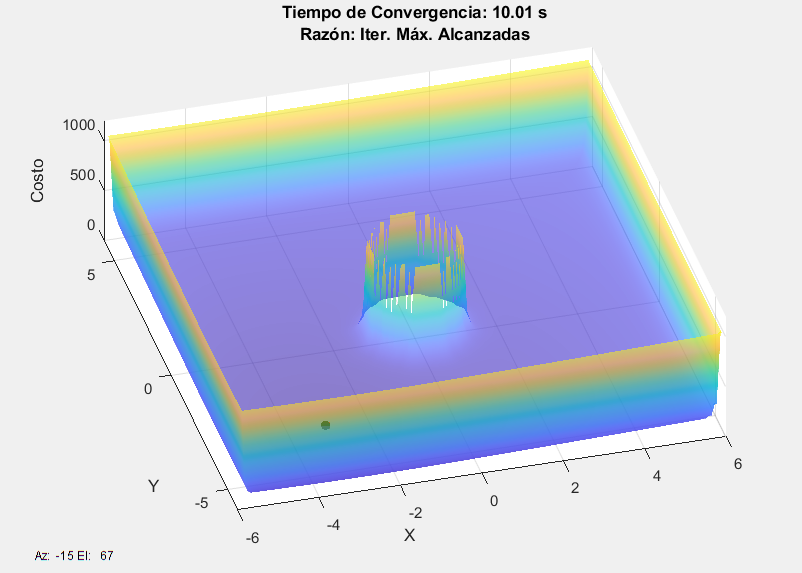

switch ModoVisualizacion
    case "2D"
        if EnablePucks
            % Gráfica de trayectorias seguidas por los E-Pucks
            for i = 1:NoParticulas
                Trayectoria = plot(PuckPosicionX_History(i,1:IteracionesFin-1), PuckPosicionY_History(i,1:IteracionesFin-1), ...
                                   'Color', [0.8, 0.2, 0.14], 'HandleVisibility', 'off' ,'LineWidth', 2);
                Trayectoria.Color(4) = 0.4;
            end
        
            % Gráfica de puntos iniciales
            PuntosIniciales = scatter(PuckPosicionX_History(:,1), PuckPosicionY_History(:,1), 'b', 'HandleVisibility', 'off' ,'LineWidth', 1.5);
            legend([PlotParticulas(1) PlotPucks(1) PlotPuntoMin(1) PuntosIniciales(1)],"Marcadores PSO", "E-Pucks", "Meta","Puntos de Partida", 'Location',"bestoutside");
        else
            % Gráfica de trayectorias seguidas por los marcadores PSO
            for i = 1:NoParticulas
                Trayectoria = plot(Part.Posicion_History{1}(i,1:IteracionesFin-1), Part.Posicion_History{2}(i,1:IteracionesFin-1), ...
                                   'Color', [0.8, 0.2, 0.14], 'HandleVisibility', 'off' ,'LineWidth', 2);
                Trayectoria.Color(4) = 0.4;
            end
        
            % Gráfica de puntos iniciales
            PuntosIniciales = scatter(Part.Posicion_History{1}(:,1), Part.Posicion_History{2}(:,1), 'b', 'HandleVisibility', 'off' ,'LineWidth', 1.5);
            legend([PlotParticulas(1) PlotPuntoMin(1) PuntosIniciales(1)],"Marcadores PSO", "Meta","Puntos de Partida",'Location',"bestoutside");
        end

    case "3D"
        % Gráfica de trayectorias seguidas por los E-Pucks
        for i = 1:NoParticulas
            Trayectoria = plot3(PuckPosicionX_History(i,1:IteracionesFin-1), PuckPosicionY_History(i,1:IteracionesFin-1), ...
                                AlturaPlanoMesa*ones(size(PuckPosicionX_History(i,1:IteracionesFin-1))), ...
                                'Color', [0.8, 0.2, 0.14], 'HandleVisibility', 'off' ,'LineWidth', 2);
        end
        
        % Gráfica de puntos iniciales
        PuntosIniciales = scatter3(PuckPosicionX_History(:,1), PuckPosicionY_History(:,1), AlturaPlanoMesa*ones(size(PuckPosicionX_History(:,1))), 'b', 'HandleVisibility', 'off' ,'LineWidth', 1.5);

end


if SaveVideo
    Frame = getframe(gcf);
    writeVideo(Video,Frame);
    close(Video); 
end


k = 2;
XDab = Part.Posicion_History{1}(:,k);
YDab = Part.Posicion_History{2}(:,k);

%YeetDists = getDistPoint2Poly(XDab,YDab,VerticesObs(:,1),VerticesObs(:,2))
%MegaDists = getDistPoint2Poly(XDab,YDab,VerticesMesa(:,1),VerticesMesa(:,2))
%SupaDists = getDistPoint2Poly(XDab,YDab,VerticesAll(:,1),VerticesAll(:,2))

Dists(:,k)

ans =     2.4649
    2.1117
    2.0972
    1.9830
    2.7804
    2.7247
    2.8141
    1.4921
    2.5361
    1.9307


### Reporte de Resultados

#### `Gráfica 1: Evoución del Costo Global Best en el Tiempo`

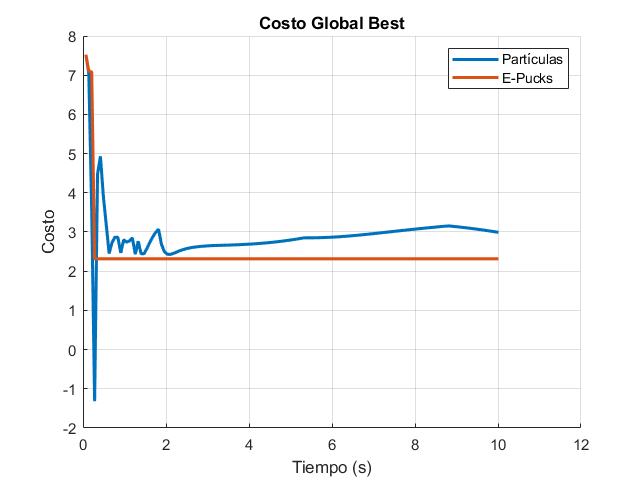

figure('Name',"Minimización de Función de Costo"); clf;
hold on; grid on;

PlotCostoPart = plot((1:IteracionesFin)*dt, Costo_History(1:IteracionesFin,1), 'LineWidth', 2);                                             % Plot: Historia de los mejores costos obtenidos por el PSO.
PlotCostoPuck = plot((1:IteracionesFin)*dt, Costo_History(1:IteracionesFin,2), 'LineWidth', 2);                                             % Plot: Historia de los mejores costos obtenidos por los pucks.

title("Costo Global Best");
legend("Partículas", "E-Pucks");
xlabel('Tiempo (s)'); ylabel('Costo');

#### `Gráfica 2: Medida de la Dispersión de las Partículas.`

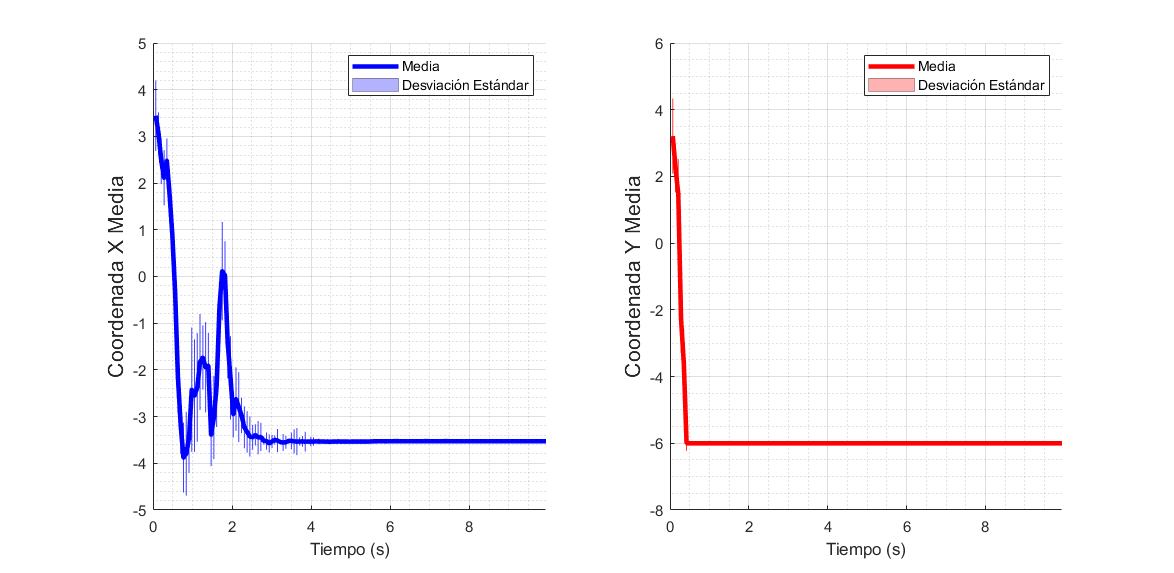

figure('Name',"Media y Desviación Estándar de Posiciones de Marcadores PSO", 'Position', [100, 100, 1024, 500]); clf;

% Filtrado de datos para deplegar iteraciones previas a la convergencia de las partículas
Part.Posicion_History{1}(:,IteracionesFin:end) = [];                                                                        % Filtrado dimensión X
Part.Posicion_History{2}(:,IteracionesFin:end) = [];                                                                        % Filtrado dimensión Y

% Dispersión de partículas sobre eje X
PartPosMediaX = median(Part.Posicion_History{1});                                                                           % Posición X media para cada iteración
PartDesvEstX = std(Part.Posicion_History{1});                                                                               % Desviación estándar para la posición X de las partículas

subplot(1,2,1); hold on;
DesvEstX = fill([(1:IteracionesFin-1)*dt; (1:IteracionesFin-1)*dt], ...
                [PartPosMediaX - PartDesvEstX; PartPosMediaX + PartDesvEstX], 'b','EdgeColor','b','EdgeAlpha',0.5);         % Fill: Evolución de la dispersión de las partículas en el tiempo
MedianaX = plot((1:IteracionesFin-1)*dt, PartPosMediaX,'b', 'LineWidth', 3);                                                % Plot: Evolución de la mediana de todas las coords X de las partículas
AreaColorX = area([0.0001 0.0002],[0.0001 0.0002],'FaceColor','b','FaceAlpha',.3,'EdgeAlpha',.3,'ShowBaseLine','off');      % Area: Usada para que en leyenda aparezca un color similar al de las líneas del fill.

ylabel("Coordenada X Media",'FontSize',14); xlabel("Tiempo (s)");
xlim([0 (IteracionesFin-1)*dt]);
legend([MedianaX(1) AreaColorX(1)],"Media","Desviación Estándar");
grid on; grid minor;

% Dispersión de partículas sobre eje Y
PartPosMediaY = median(Part.Posicion_History{2});                                                                           % Posición Y media para cada iteración
PartDesvEstY = std(Part.Posicion_History{2});                                                                               % Desviación estándar para la posición Y de las partículas

subplot(1,2,2); hold on;

DesvEstY = fill([(1:IteracionesFin-1)*dt; (1:IteracionesFin-1)*dt], ...
                [PartPosMediaY - PartDesvEstY; PartPosMediaY + PartDesvEstY], 'r','EdgeColor','r','EdgeAlpha',0.5);         % Fill: Evolución de la dispersión de las partículas en el tiempo
MedianaY = plot((1:IteracionesFin-1)*dt, PartPosMediaY,'r','LineWidth', 3);                                                 % Plot: Evolución de la mediana de todas las coords Y de las partículas
AreaColorY = area([0.0001 0.0002],[0.0001 0.0002],'FaceColor','r','FaceAlpha',.3,'EdgeAlpha',.3,'ShowBaseLine','off');      % Area: Usada para que en leyenda aparezca un color similar al de las líneas del fill.

ylabel('Coordenada Y Media','FontSize',14); xlabel("Tiempo (s)");
xlim([0 (IteracionesFin-1)*dt]);
legend([MedianaY(1) AreaColorY(1)],"Media","Desviación Estándar");
grid on; grid minor;

#### `Gráfica 3: Velocidad de Motores de Robot`

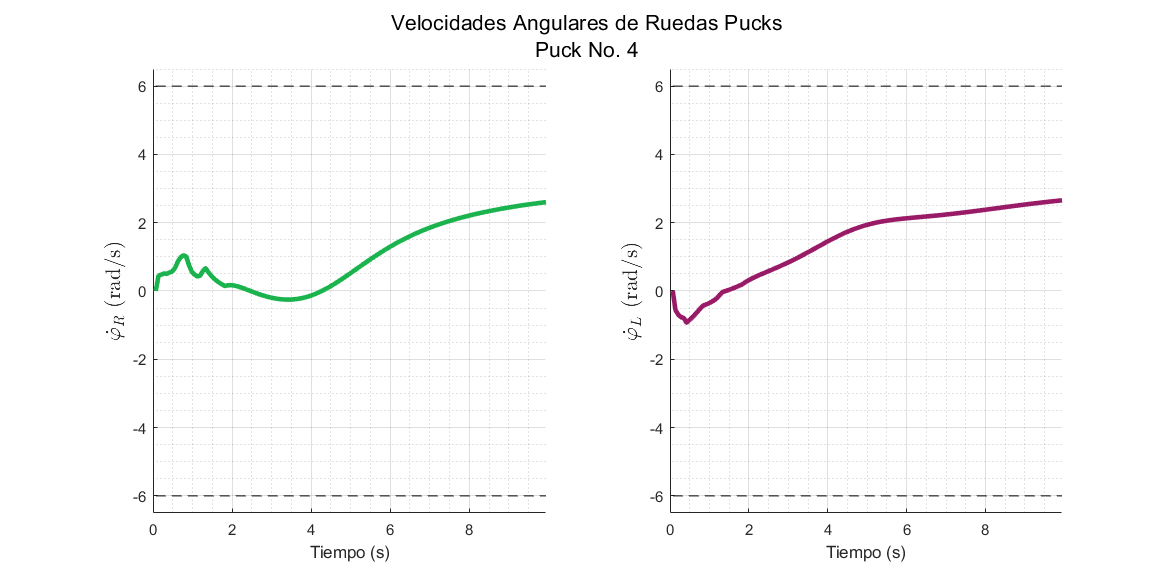

% Cálculo de las velocidades lineal y angular de los diferentes robots
% utilizando su "cinemática inversa".
VelAngularRuedaDer = (2*PuckVelLineal_History + 2*PuckVelAngular_History*RadioCuerpoPuck) / (2*RadioLlantasPuck);
VelAngularRuedaIzq = (2*PuckVelLineal_History - 2*PuckVelAngular_History*RadioCuerpoPuck) / (2*RadioLlantasPuck);

% Filtrado de datos para deplegar iteraciones previas a la convergencia
% de las partículas
VelAngularRuedaDer(:,IteracionesFin:end) = [];
VelAngularRuedaIzq(:,IteracionesFin:end) = [];

% Selección del Puck con las velocidades más altas
VelsAngularesMedias = [median(VelAngularRuedaDer,2) median(VelAngularRuedaIzq,2)];
[~,PuckAnalizado] = max(median(VelsAngularesMedias,2));

Fig_Velocidades = figure('Name',"Velocidades Ruedas Puck", 'Position', [100, 100, 1024, 500]);
sgtitle({"Velocidades Angulares de Ruedas Pucks"; "Puck No. " + num2str(PuckAnalizado)});

% Gráfica de evolución de velocidad angular de rueda derecha
subplot(1,2,1); hold on;
VelocidadRuedaDer = plot((1:IteracionesFin-1)*dt,VelAngularRuedaDer(PuckAnalizado,:),'Color', [0.1 0.7 0.3],'LineWidth',3);
LimiteSuperiorDer = plot((1:IteracionesFin-1)*dt,PuckVelMax*ones(1,IteracionesFin-1),'--','Color','black');
LimiteInferiorDer = plot((1:IteracionesFin-1)*dt,-PuckVelMax*ones(1,IteracionesFin-1),'--','Color','black');

ylabel('$\dot{\varphi}_R$ (rad/s)','FontSize',14,'Interpreter',"latex"); 
xlabel("Tiempo (s)");
xlim([0 (IteracionesFin-1)*dt]); ylim([-PuckVelMax-0.5 PuckVelMax+0.5]);
grid on; grid minor;

% Gráfica de evolución de velocidad angular de rueda izquierda
subplot(1,2,2); hold on;
VelocidadRuedaIzq = plot((1:IteracionesFin-1)*dt, VelAngularRuedaIzq(PuckAnalizado,:),'Color', [0.6 0.1 0.4],'LineWidth',3);
LimiteSuperiorIzq = plot((1:IteracionesFin-1)*dt,PuckVelMax*ones(1,IteracionesFin-1),'--','Color','black');
LimiteInferiorIzq = plot((1:IteracionesFin-1)*dt,-PuckVelMax*ones(1,IteracionesFin-1),'--','Color','black');

ylabel('$\dot{\varphi}_L$ (rad/s)','FontSize',14,'Interpreter',"latex"); 
xlabel("Tiempo (s)");
xlim([0 (IteracionesFin-1)*dt]); ylim([-PuckVelMax-0.5 PuckVelMax+0.5]);
grid on; grid minor;

#### `Gráfica 4: Cálculo de la Suavidad de Velocidades`

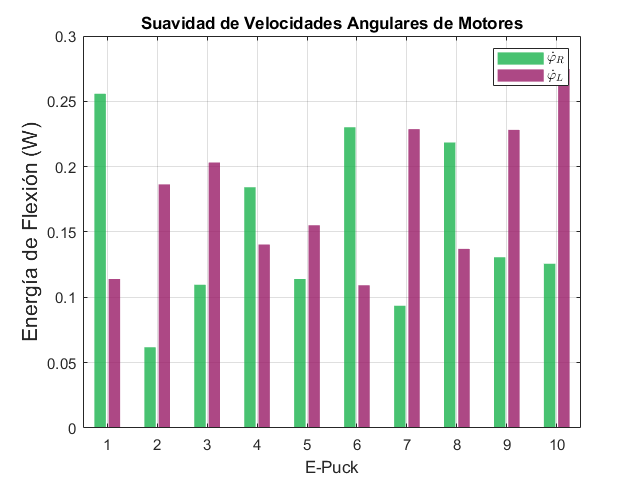


EnergiaFlexionDer = zeros(NoParticulas,1);
EnergiaFlexionIzq = zeros(NoParticulas,1);

for i = 1:NoParticulas
    EnergiaFlexionDer(i) = getSuavidadTrayectoria(VelAngularRuedaDer(i,:),2,0);
    EnergiaFlexionIzq(i) = getSuavidadTrayectoria(VelAngularRuedaIzq(i,:),2,0);
end

EnergiaFlexion = [EnergiaFlexionDer EnergiaFlexionIzq];

figure("Name","Flexión por E-Puck"); clf;

BarrasEnergia = bar(1:NoParticulas,EnergiaFlexion,'FaceColor','Flat','FaceAlpha',0.8,'EdgeAlpha',0);
BarrasEnergia(1).CData = [0.1 0.7 0.3];
BarrasEnergia(2).CData = [0.6 0.1 0.4];

xlabel("E-Puck");
ylabel("Energía de Flexión (W)",'FontSize',14);
title("Suavidad de Velocidades Angulares de Motores");
legend("$\dot{\varphi}_R$", "$\dot{\varphi}_L$",'Interpreter',"latex")
grid on;